# ***Bayesian Optimized Neural Network for Estimation of Gain Coefficients in Fiber Optics Amplifier***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini

This script is a primary code that included in the research paper for comprehensive analysis with FNN

**Instructions for Downloading and Running the Script**

- Download raw datasets of Fiber Optics Amplifier doping materials from SOTON page [http://dx.doi.org/10.5258/SOTON/D1062](http://dx.doi.org/10.5258/SOTON/D1062) and [http://dx.doi.org/10.5258/SOTON/D2402](http://dx.doi.org/10.5258/SOTON/D2402) 

- After downloading all the files including this one, unzip the file to a folder, do not modify the folder structure.

- Navigate to the folder with "BONN_Optical_Fiber.mlx".

- Open and run "BONN_Optical_Fiber.mlx".

- The matlab script should run without any modification, if there is an issue it's likely due to typos or the testing and training data not being in the expected place.

- If required to modify the script, follow the comprehensive step-by-step in README file.

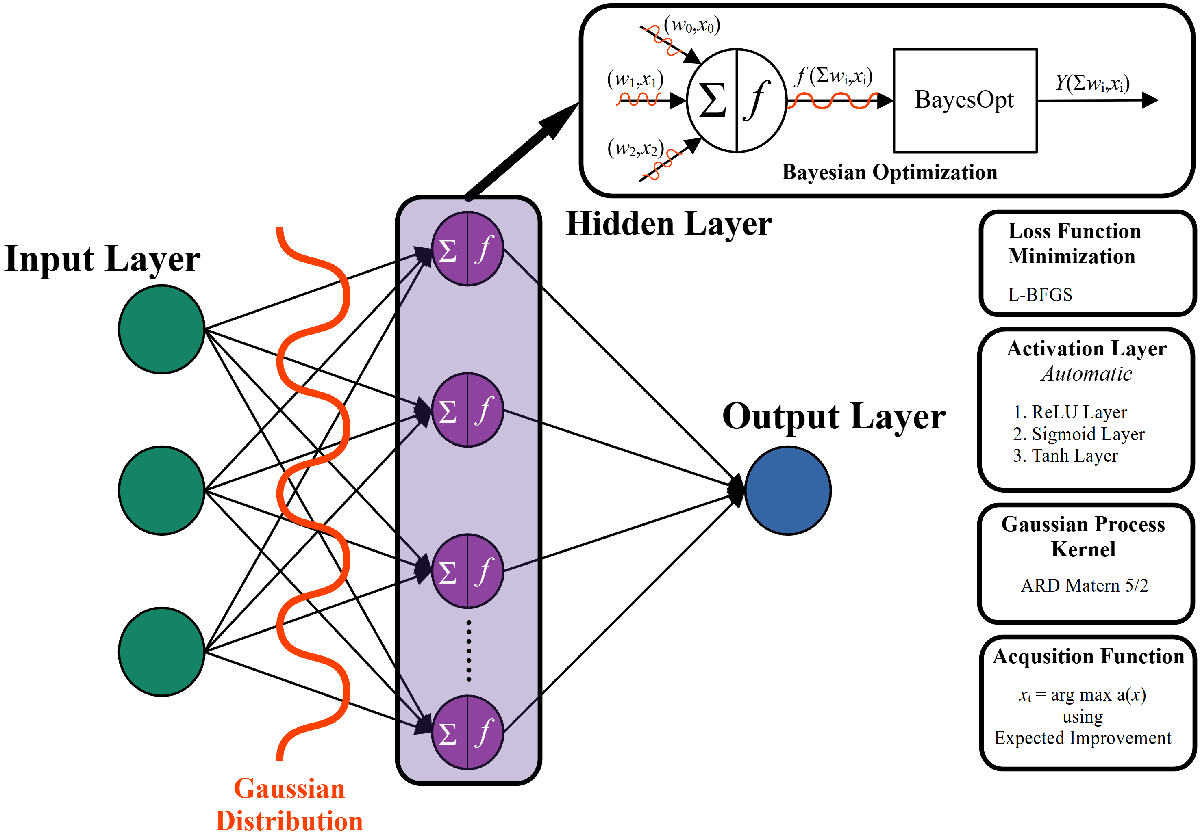

Load all of dataset. For specified coefficient, try to comment and uncomment text below. For example, if you want to perform a training at P = 0, then uncomment the code.

clear all
load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P0.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P01.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P02.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P03.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P04.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P05.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P06.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P07.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P08.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P09.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P1.mat

Split the data for Training (80%) and for Testing/Validation (20%)

rng("default")
c = cvpartition(size(Tbl,1),"Holdout",0.2);
trainingIndices = training(c);
validationIndices = test(c);
TblTrain = Tbl(trainingIndices,:);
TblValidation = Tbl(validationIndices,:);

Bayesian Optimization (BO) is a metaheuristics black-box optimization method that utilized the principle of Bayes theorem:


$$P(A|B) = \frac{P(B|A) \cdot P(A)}{P(B)}$$


Where *P*(*A*|*B*) is posterior distribution of probability, *P*(*B*|*A*) is a probability of observed evidence under the assumtion the hypothesis are true, *P*(*A*) is prior hypothesis, and *P*(*B*) is probability of an observed evidance. The intricite complexity of nonconvex function exist where the system is very hard to defined or unkown by observer, it is known as black-box system. From an optimization standpoint, the intricacies of this challenge can be defined as:


$$\max_{x \in \, \mathbb{X}} f(x) \; \text{or} \; \min_{x \in \, \mathbb{X}} f(x) \\
\qquad x \in \mathbb{X} \subset \mathbb{R}$$


Let say 𝑥 signify the multi-dimensional input representing control parameters, while 𝑓(𝑥) denotes the objective function. 𝑓(𝑥) may encapsulate a sophisticated, high-dimensional, intricately interconnected, and multiscale system. Given the inherent complexities entailed in crafting accurate and precise models for such intricate systems, it becomes imperative to address the challenge to solve those issues. BO is one of many solution of meta-black-box optimization method that very effective to find a global optimum of such expensive black-box system. BO can be defined as:


$$P(f(x)|D_{t}) = \frac{P(D_{t}|f(x)) \cdot P(f(x))}{P(D_{t})}$$


Where *P*(𝑓(𝑥)|*Dt*) is the same as *P*(*A*|*B*), *P*(*Dt*| 𝑓(𝑥)) is a is the probability of the observe data given the function value 𝑓(𝑥) in which typically assumed to be Gaussian with mean 𝑓(𝑥) and observation noise variance, *P*(𝑓(𝑥)) is the prior distribution over 𝑓(𝑥) in which is the Gaussian process (GP) prior, and *P*(*Dt*) is the evidence acts as a normalization constant. 

The process of BO to find the best possible optimum solution is through exploring & exploiting the system. Exploiting the system through selection of training option and hyperparameter tuning, while the exploration of the system is through Gaussian process of acquisition function α(*x*). Acquisition function act as a predictive method through searching the space of Gaussian and Bayesian distribution of the GP. α(*x*) can be defined as:


$$x_{t} = \arg \, \max \; \alpha(x) \\
\qquad \; \; x \in \mathbb{X}$$


There are a lot of types of acquisition function availabe on the literature, some of them are: Probability of Improvement (PI), Expected Improvement (EI), Lower Confidence Bound (LCB), Upper Confidence Bound (UCB), Thomson Scalling, etc. For this research, EI is our selection of acquisition function with the following expression:


$$\alpha_{EI}(x) = \mathbb{E}[I(x)]$$


The open-form of EI:


$$\alpha_{EI}(x) = \int_{-\infty}^{\infty} I(x) \; P(Y|x) \; dY$$


The acquisition of improvement $I(x)$ act as the temporary improvement for EI based from $P(Y|x)$ the predictive marginal density of the objective function at $x$.


$$\text{Where:} \quad I(x) = \max(f(x)-Y,0)$$


Using Monte Carlo integration nor quasi-Monte Carlo sampling, We can simplified the open-form EI into closed-form:


$$\alpha_{EI}(x) = \begin{cases} (\mu(x)-Y-\zeta) \; \Phi(Z)+\sigma(x) \; \phi(Z), \; \text{for} \; \sigma(x) > 0 \\ 0, \qquad \qquad \qquad \qquad \quad \qquad \qquad \; \, \text{for} \; \sigma(x) = 0 \\ \end{cases}$$



$$\text{Where:} \quad Z = \frac{\mu(x)-Y-\zeta}{\sigma(x)}$$


$\Phi (.)$ denotes the cumulative distribution function (CDF), $\varphi (.)$ represents the probability density function (PDF), $𝜁$ signifies the exploration ratio of Expected Improvement (EI), $𝜇(𝑥)$ denotes the mean function of the Gaussian Process, and $𝜎(𝑥)$ represents the level of uncertainty.

The aim of the EI algorithm is to maximize the expected improvement over the current best observation. The expected improvement at a point $x$ is defined as the expected value of the improvement in the objective function value compared to the current best observation. 

Based from the information above, began neural network training using Bayesian Optimization

|============================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda |            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |                       |
|============================================================================================================================================|
|    1 | Error  |         NaN |      1.1906 |         NaN |         NaN |         relu |         true |   5.4079e-06 |  169                  |
|    2 | Error  |         NaN |     0.38383 |         NaN |         NaN |         relu |         true |   1.6042e-07 | [  1   5]             |
|    3 | Error  |         NaN |     0.30272 |         NaN |         NaN |      sigmoid |        false |      0.62589 | [ 10   6   2]         |

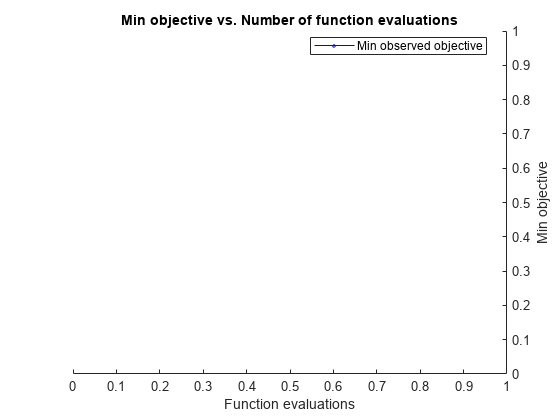


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 31.0453 seconds
Total objective function evaluation time: 5.8876
No feasible points were found.
|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.342588|    0.275308|    0.551430|    0.036696|    0.376125|           0|
|           2|    0.095161|    0.106361|    0.185872|    0.006674|    0.193662|           0|
|           3|    0.020663|    0.033538|    0.186320|    0.004523|    0.064126|           0|
|           4|    0.014996|    0.039338|    0.037580|    0.007296|    0.056081|

Mdl_BONN = fitrnet(TblTrain, 'Gain Coeff p0', ...
    'Standardize', 1, ...
    'OptimizeHyperparameters', 'auto', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', ...
    'AcquisitionFunctionName', 'expected-improvement'), ...
    'ValidationData', TblValidation, ...
    'Verbose', 1);

Summerize training results

Train.iteration = Mdl_BONN.TrainingHistory.Iteration;
Train.trainLosses = Mdl_BONN.TrainingHistory.TrainingLoss;
Train.valLosses = Mdl_BONN.TrainingHistory.ValidationLoss;
Train.time = Mdl_BONN.TrainingHistory.Time;
Train.Bayes_time = Mdl_BONN.HyperparameterOptimizationResults.IterationTimeTrace;
Train.Bayes_eval_time = Mdl_BONN.HyperparameterOptimizationResults.ObjectiveEvaluationTimeTrace;

Calculate total estimated time in seconds

TotalTime.time = sum(Train.time,"all");
disp(TotalTime.time)

    0.1240



TotalTime.Bayes_time = sum(Train.Bayes_time,"all");
disp(TotalTime.Bayes_time)

   30.7200



TotalTime.Bayes_eval_time = sum(Train.Bayes_eval_time,"all");
disp(TotalTime.Bayes_eval_time)

    5.8876



TotalTime.total_time = TotalTime.time + TotalTime.Bayes_time + TotalTime.Bayes_eval_time;
disp(TotalTime.total_time)

   36.7316



Plotting Mean Square Error from training

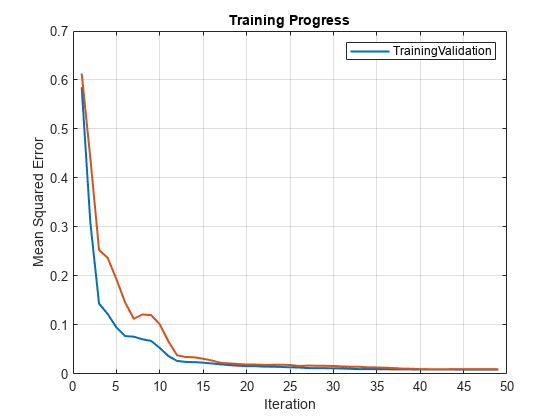

figure
plot(Train.iteration,sqrt(Train.trainLosses),Train.iteration,sqrt(Train.valLosses),'LineWidth',1.5)
legend(['Training','Validation'])
xlabel('Iteration')
ylabel('Mean Squared Error')
title('Training Progress')
grid on

Plotting Mean Square Error from training

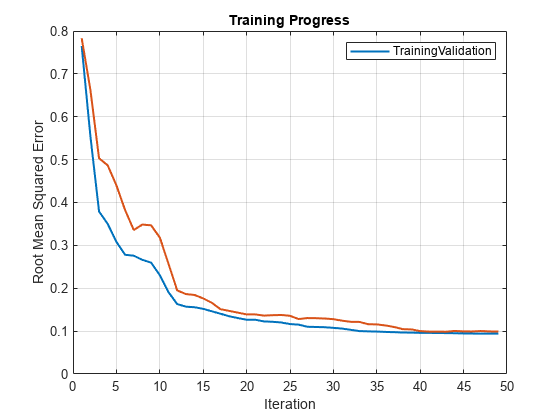

figure
plot(Train.iteration,sqrt(sqrt(Train.trainLosses)),Train.iteration,sqrt(sqrt(Train.valLosses)),'LineWidth',1.5)
legend(['Training','Validation'])
xlabel('Iteration')
ylabel('Root Mean Squared Error')
title('Training Progress')
grid on

Calculate the prediction error and prediction RMSE

testPredictions = predict(Mdl_BONN,X);
Error_test = testPredictions - GainCoefficient_p0;
RMSE = sqrt(mean((Error_test).^2))*100;

Plot the results

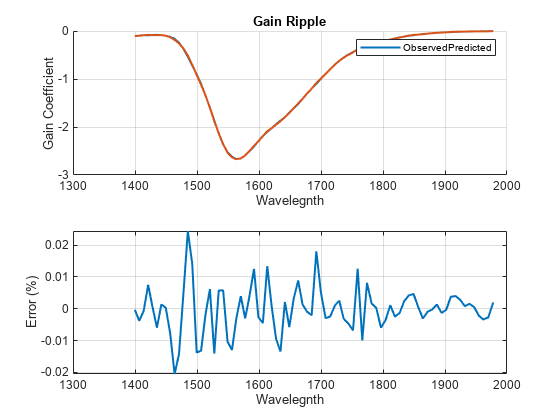

figure
subplot(2,1,1)
hold all
grid on
plot(GainCoefficient_Wave,GainCoefficient_p0,'LineWidth',1.5)
plot(GainCoefficient_Wave,testPredictions,'LineWidth',1.5)
legend(['Observed' 'Predicted'])
xlabel('Wavelegnth')
ylabel('Gain Coefficient')
title('Gain Ripple')
subplot(2,1,2)
plot(GainCoefficient_Wave,GainCoefficient_p0,'LineWidth',1.5)
plot(GainCoefficient_Wave,Error_test,'LineWidth',1.5)
xlabel('Wavelegnth')
ylabel('Error (%)')
grid on

## Copyright Notice

This code is the original works by Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini under MIT 2.0 licence. All right reserved.

## Reference

[1] Chen, Jung, Alam, Richardson, Sidharthan, Ho, Yoo, & Daniel. (2020, March 18). *Dataset for: Ultra-short wavelength operation of thulium doped fiber amplifiers and lasers*. ePrints Soton. [https://eprints.soton.ac.uk/438624/](https://eprints.soton.ac.uk/438624/) 

[2] Zhai, Halder, & Sahu. (2023, March 1). *Data in support of the conference paper “erbium-doped fiber amplifier with extended L-band gain to 1625 nm.”* ePrints Soton. [https://eprints.soton.ac.uk/475237/](https://eprints.soton.ac.uk/475237/) 